Filas = Salidas x,y,z,psi

Columnas = Entradas 

Gs 4x4

clc; clear all; close all;

% Constantes
m = 1.79;      g= 9.77412;
Ix = 0.03;     Iy = 0.03;
Iz = 0.04;     T = 0.01;

Ac = [0 0 0 0  0 0 1 0 0 0 0 0 ;
     0 0 0 0  0 0 0 1 0 0 0 0 ;
     0 0 0 0  0 0 0 0 1 0 0 0 ;
     0 0 0 0  0 0 0 0 0 1 0 0 ;
     0 0 0 0  0 0 0 0 0 0 1 0 ;
     0 0 0 0  0 0 0 0 0 0 0 1 ;
     0 0 0 0 -g 0 0 0 0 0 0 0 ;
     0 0 0 g  0 0 0 0 0 0 0 0 ;
     0 0 0 0  0 0 0 0 0 0 0 0 ;
     0 0 0 0  0 0 0 0 0 0 0 0 ;
     0 0 0 0  0 0 0 0 0 0 0 0 ;
     0 0 0 0  0 0 0 0 0 0 0 0];

Bc = [0 0 0 0;
     0 0 0 0;
     0 0 0 0;
     0 0 0 0;
     0 0 0 0;
     0 0 0 0;
     0 0 0 0;
     0 0 0 0;
     -1/m 0 0 0;
     0 1/Ix 0 0;
     0 0 -1/Iy 0;
     0 0 0 -1/Iz];

Cc = [1 0 0 0 0 0 0 0 0 0 0 0 ;
      0 1 0 0 0 0 0 0 0 0 0 0 ;
      0 0 1 0 0 0 0 0 0 0 0 0 ;
      0 0 0 0 0 1 0 0 0 0 0 0 ];

Dc = zeros(4,4);

h = 0.01;
% Con h=0.1 dió mejor
[Ap,Bp,Cp,Dp]=c2dm(Ac,Bc,Cc,Dc,h,'zoh');
[m1,n1]=size(Cp);
[n1,n_in]=size(Bp);

% Polos de las funciones de Laguerre
a1=0.8;
a2=0.8;
a3=0.8;
a4=0.8;

% Número de términos para la función de Laguerre
N1=10;
N2=10;
N3=10;
N4=10;

a=[a1 a2 a3 a4];
N=[N1 N2 N3 N4];
Np=100;

A_e=eye(n1+m1,n1+m1);
A_e(1:n1,1:n1)=Ap;
A_e(n1+1:n1+m1,1:n1)=Cp*Ap;
B_e=zeros(n1+m1,n_in);
B_e(1:n1,:)=Bp;
B_e(n1+1:n1+m1,:)=Cp*Bp;
C_e=zeros(m1,n1+m1);
C_e(:,n1+1:n1+m1)=eye(m1,m1);
Q=C_e'*C_e;
R=0.1*eye(n_in,n_in);

[Omega,Psi]=dmpc(A_e,B_e,a,N,Np,Q,R);
L_m=zeros(n_in,sum(N));
[A1,L0]=lagd(a(1),N(1));
L_m(1,1:N(1))=L0';
In_s=1;
for jj=2:n_in
    [Al,L0]=lagd(a(jj),N(jj));
    In_s=N(jj-1)+In_s;
    In_e=In_s+N(jj)-1;
    L_m(jj,In_s:In_e)=L0';
end
K=L_m*(Omega\Psi);
Acl=A_e-B_e*K;

El programa anterior produce el control predictivo del modelo de tiempo discreto usando funciones de Laguerre. La ganancia de control de retroalimentación de estado es K y la matriz del sistema de bucle cerrado es Acl.

**dlqr():** Regulador lineal cuadrático (LQ) de feedback de estados para un sistema de espacio de estados de tiempo discreto.

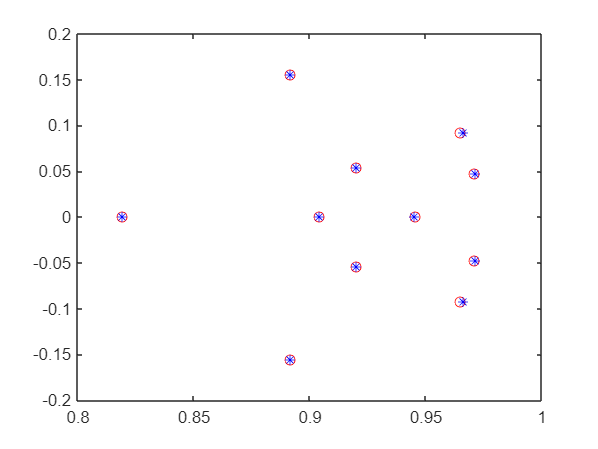

[X,Y,Z]=dlqr(A_e,B_e,Q,R);
% Z = e = eig(A-B*K)
figure
plot(Z,'ro')        % Polos del DLQR
hold on
plot(eig(Acl),'b*') % Polos del MPC

A continuación,simularemos la respuesta del sistema en lazo cerrado usando la función **simuuc.m**

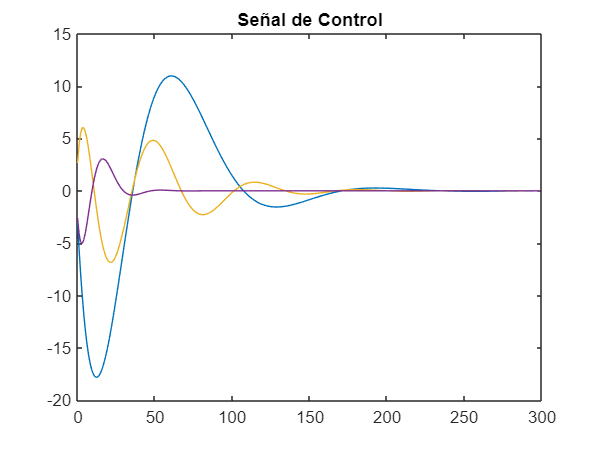

y=zeros(m1,1);
u=zeros(n_in,1);
xm=zeros(n1,1);
N_sim=300;
r1=ones(1,N_sim+10);
r2=ones(1,N_sim+10);
r3=ones(1,N_sim+10);
r4=ones(1,N_sim+10);

% Set-Point
sp=[r1;r2;r3;r4];
[M,Lzerot]=Mdu(a,N,n_in,1);
[u1,y1,deltau1,k]=simuuc(xm,u,y,sp,Ap,Bp,Cp,N_sim,Omega,Psi,Lzerot);

figure
plot(k,u1)
title('Señal de Control')

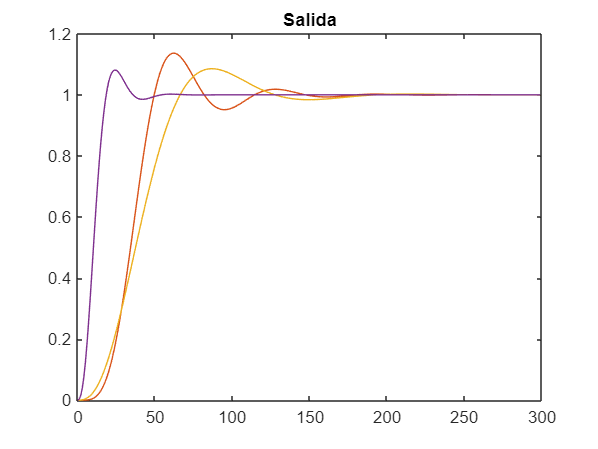


figure
plot(k,y1)
title('Salida')

## Diseño con las dos restricciones

[Omega,Psi]=dmpc(A_e,B_e,a,N,Np,Q,R);

% Condiciones iniciales
X0=[0.1*ones(16,1)];

up=6;

                

% Restricciones
Deltau_min=-1;
Deltau_max=0.25;
u_min=1.02;
u_max=1.02;

% Se definen las restricciones,
Nc=Np;
[M1,Lzerot]=Mdu(a,N,1,Nc);
M0=Mu(a,N,1,Nc);
M=[M0;-M0;M1;-M1];

% Restricciones
gamma=[(u_max-up)*ones(Nc,1);(-u_min+up)*ones(Nc,1);
       Deltau_max*ones(Nc,1); -Deltau_min*ones(Nc,1)];
eta=QPhild(Omega,Psi*X0,M,gamma);

% A_e = 16x16
% B_e = 16x4
% Psi = 40x16
% X0 = 12x1   

Gráficas

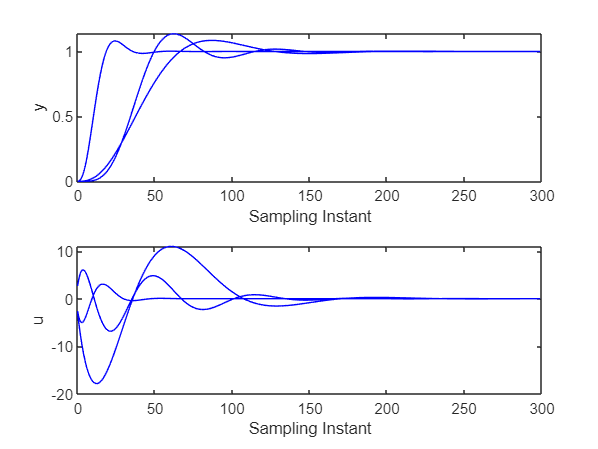

k=0:(N_sim-1);

figure(5)
subplot(211)
plot(k,y1,'b')
ylabel('y')
xlabel('Sampling Instant')
subplot(212)
plot(k,u1,'b')
ylabel('u')
xlabel('Sampling Instant')

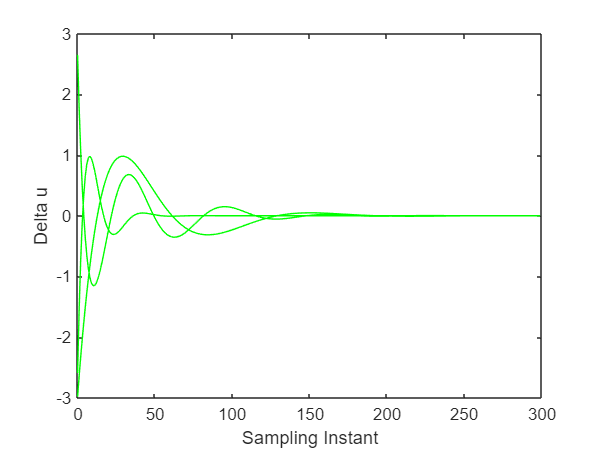


figure(6)
plot(k,deltau1,'g')
ylabel('Delta u')
xlabel('Sampling Instant')